## 4.2 Disturbance attenuation

#### Requirements


$$t_{\textrm{rise}} <0\ldotp 2s$$



$$\textrm{overshoot}<0\ldotp 1$$



$$|y\left(t\right)|\le 1\;\;\forall \;t,\;\;|y\left(t\right)|\le 0\ldotp 1\;\forall t>0\ldotp 5s$$



$$|u\left(t\right)|\le 1\;\forall \;t$$


s = tf('s');

#### Exercise 4.2.1

G = 20 /( (s+1) * ((s/20)^2 + s/20 + 1))

G =
 
                
          160000
                
  ----------------------
                        
  20 s^3 + 420 s^2      
                        
          + 8400 s      
                        
                  + 8000
                        
 
Continuous-time transfer function.



G_d = 10 / (s+1)

G_d =
 
   10
  -----
  s + 1
 
Continuous-time transfer function.



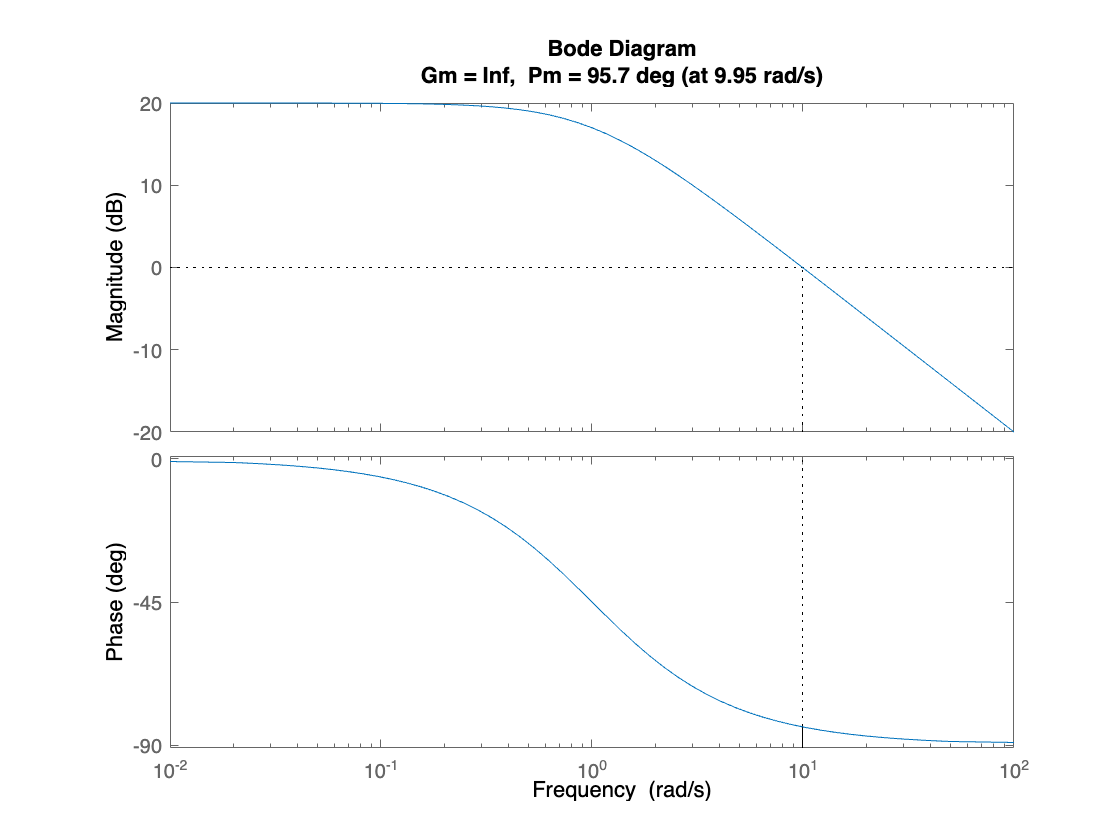

margin(G_d)

Based on the cross over frequency of G_d, the cross over frequency for the closed loop system is selected at w_c = 10.

w_c = 10;

F_y = G^(-1)* w_c/( s * (s+10)^2)

F_y =
 
                         
   200 s^3 + 4200 s^2    
                         
           + 84000 s     
                         
                  + 80000
                         
  ------------------------
                          
  160000 s^3 + 3.2e06 s^2 
                          
              + 1.6e07 s  
                          
 
Continuous-time transfer function.



### Exercise 4.2.2

Choose $w_I$ so that the system requirements are fulfilled. For the given system we decided on $w_{I\;} =100$.

w_i = 18;
p = pole(G)

p =  -10.0000 +17.3205i
 -10.0000 -17.3205i
  -1.0000 + 0.0000i


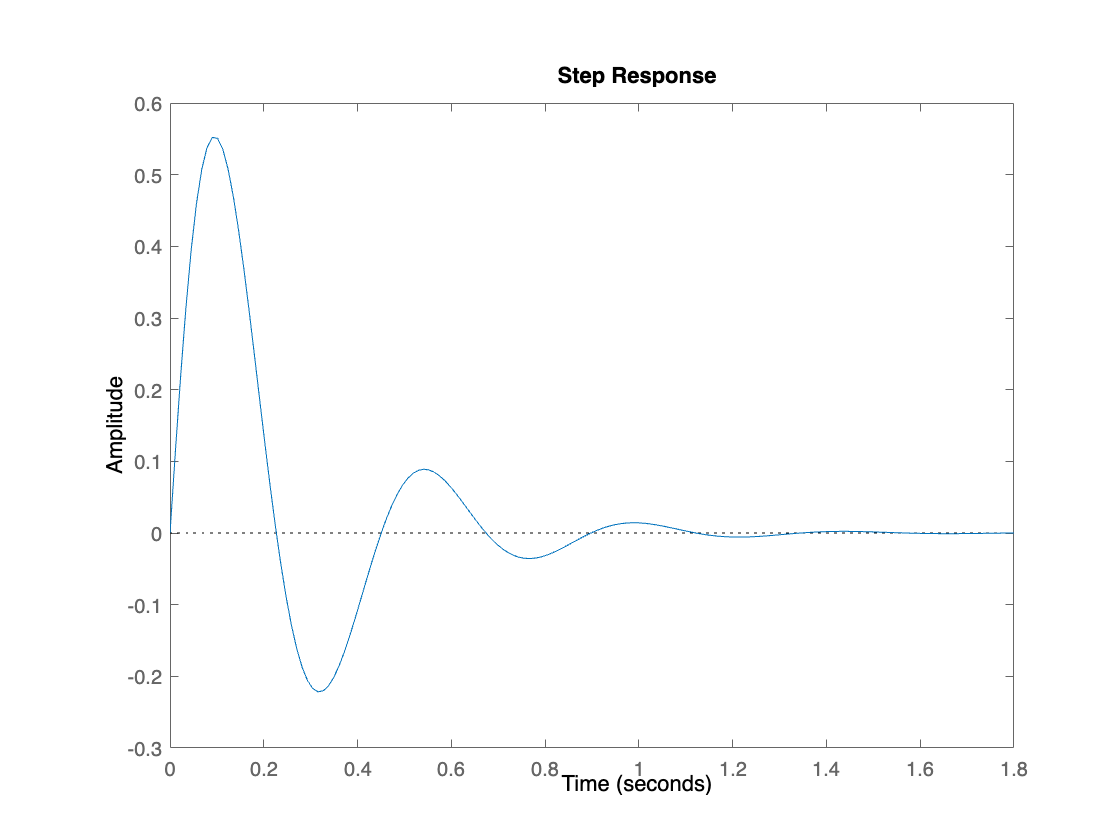

F_y = 10000* (s + w_i)/s * G_d / (G * (s+100)^2);
S = G_d/(1+ G * F_y);
step(S)

### Exercise 4.2.3

$F_r$ should be as simple as possible as to not attenuate the refrence signal to much. 

w_c = 17;
beta = 0.5;
tau_d = 1/(w_c * sqrt(beta));

F_lead = (tau_d * s + 1)/(beta*tau_d * s + 1)

F_lead =
 
  0.08319 s + 1
  -------------
  0.04159 s + 1
 
Continuous-time transfer function.



[invK, ] = bode(F_lead*F_y*G, w_c)

invK = 1.1755

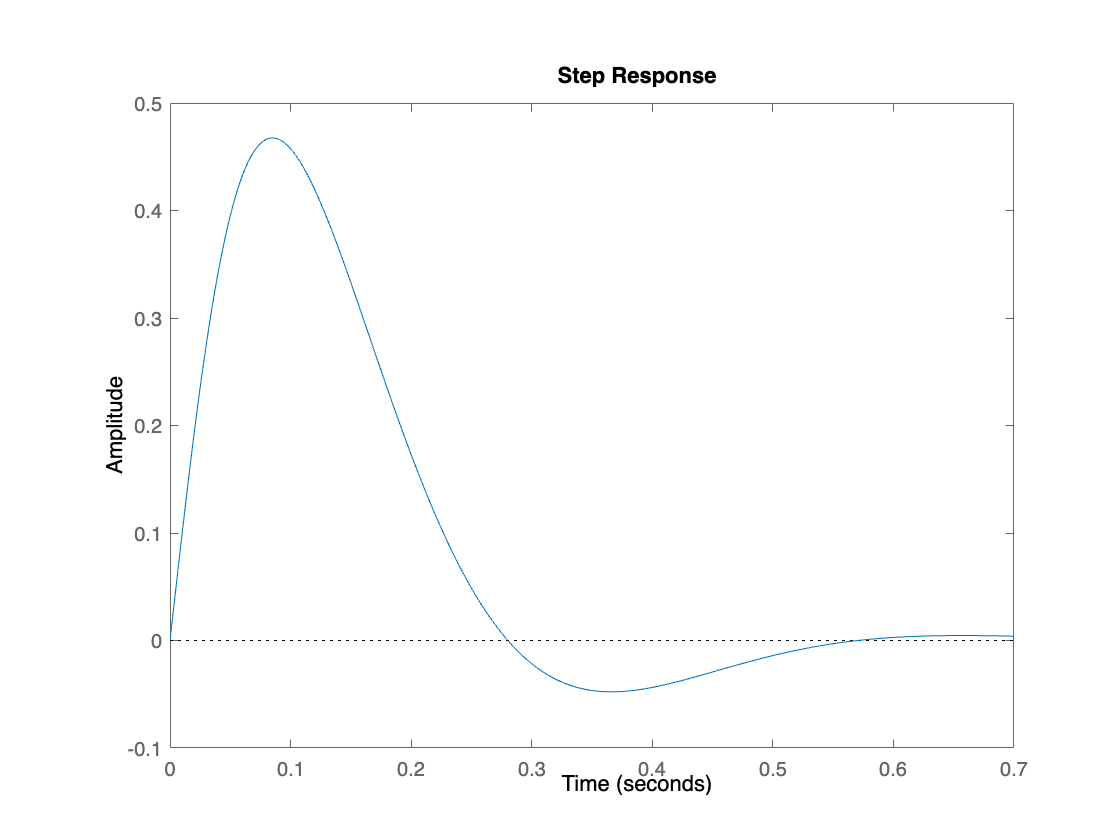

F_lead = F_lead / invK;
F_y = F_lead * F_y;
S = G_d/(1+ G*F_y);
step(S)

tau = 0.1

tau = 0.1120

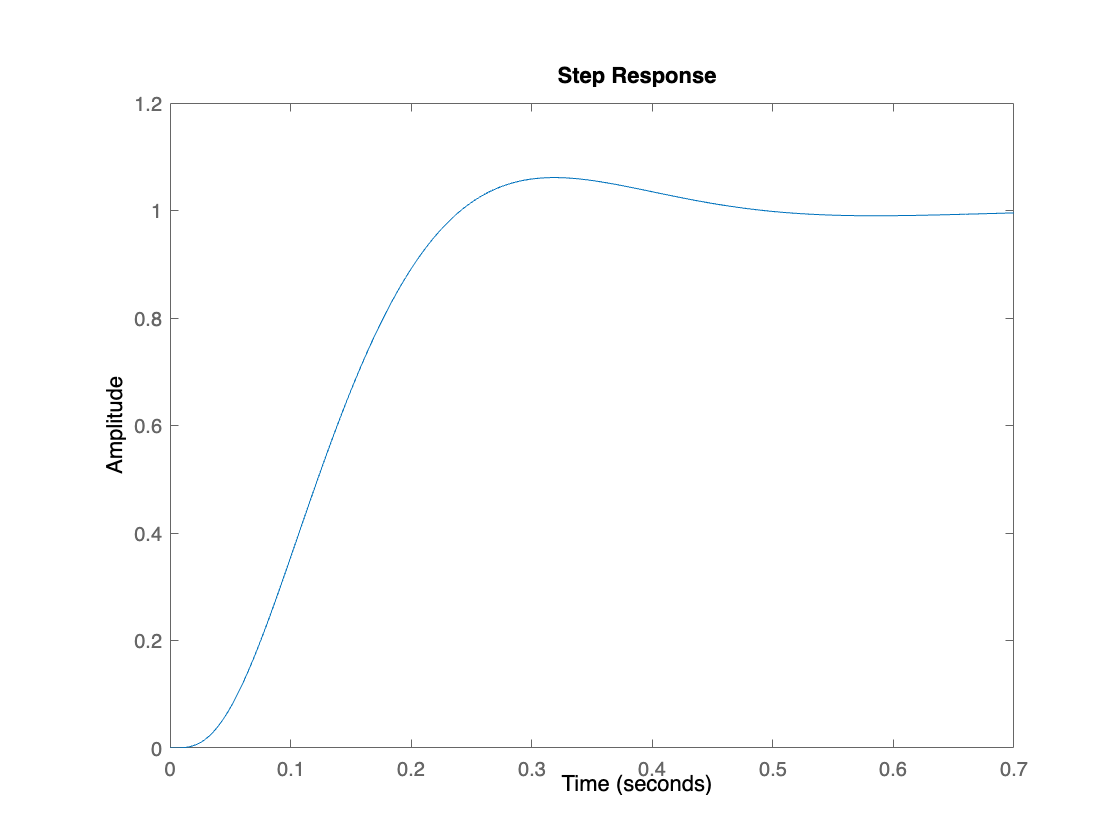

F_r = 1 / (1 + tau*s);

G_c = G * F_r * F_y / (1 + G * F_y);
step(G_c)

stepinfo(G_c)

ans = struct with fields:
         RiseTime: 0.1465
    TransientTime: 0.4329
     SettlingTime: 0.4329
      SettlingMin: 0.9005
      SettlingMax: 1.0612
        Overshoot: 6.1246
       Undershoot: 0
             Peak: 1.0612
         PeakTime: 0.3187


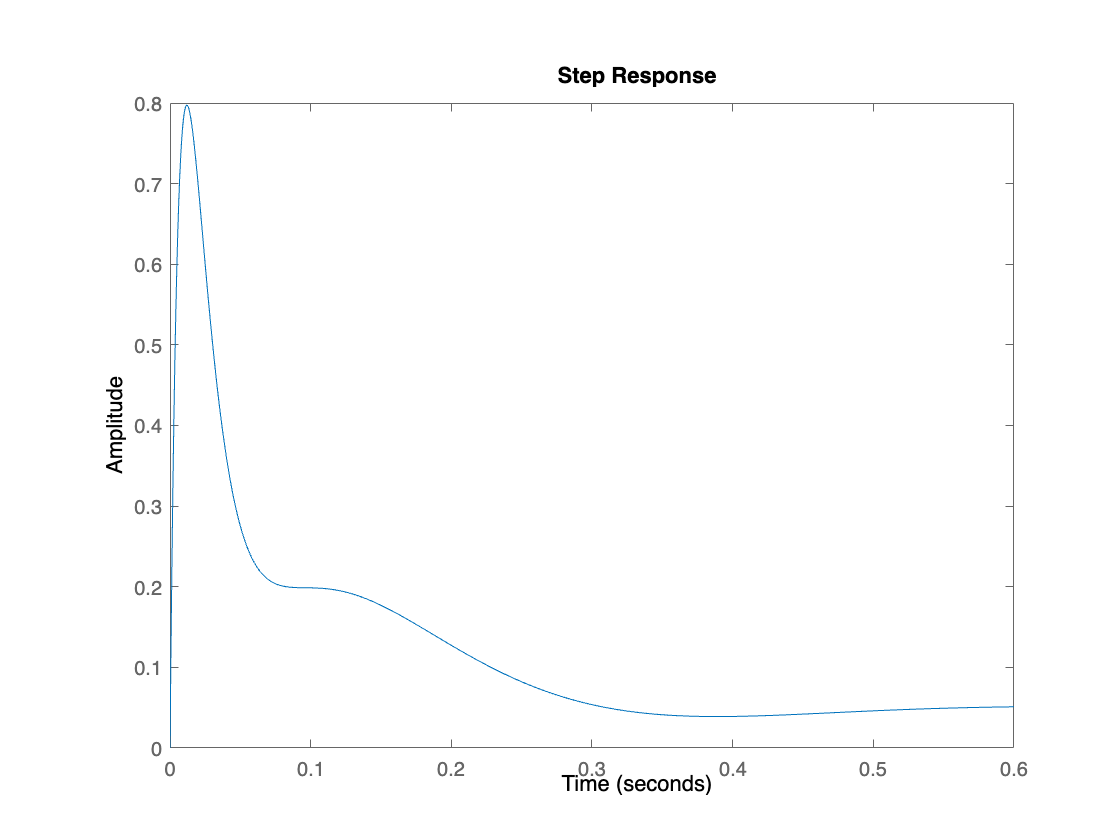

step(F_y*F_r/(1+G*F_y))

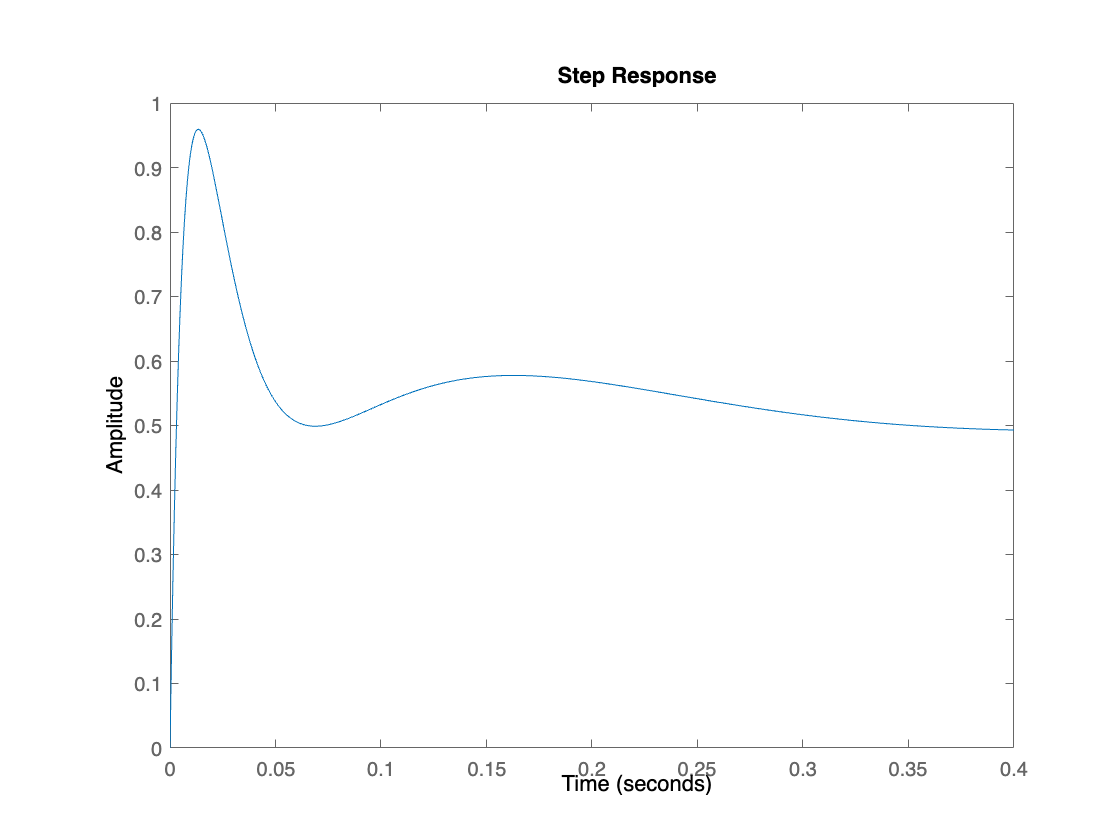

step(F_y * G_d/(1+G*F_y) )

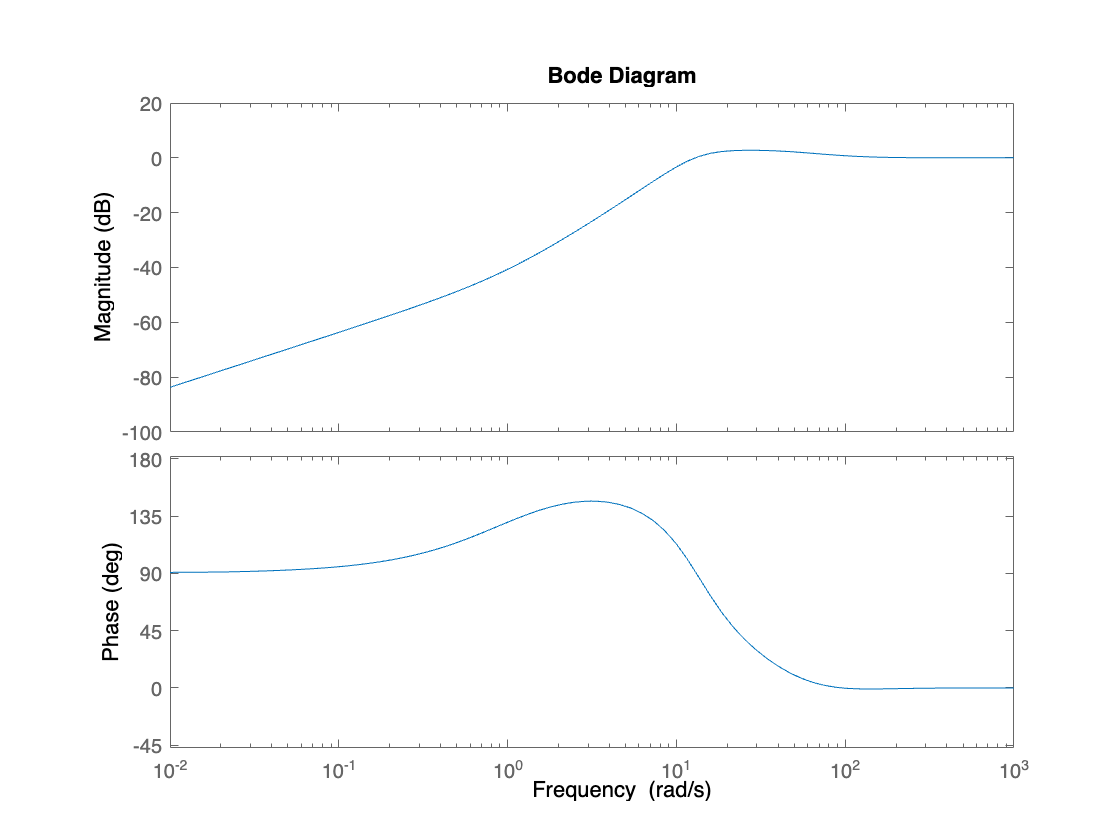

bode(1/(1+G*F_y))

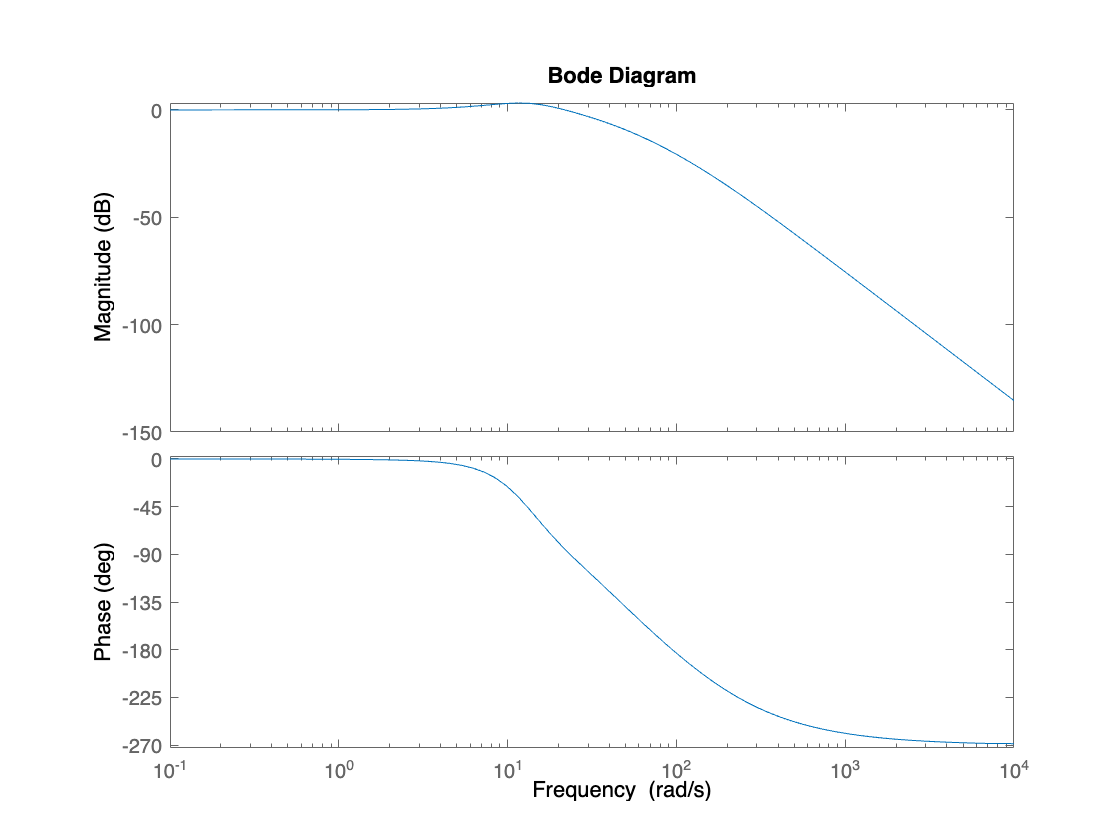

bode(G*F_y/(1+G*F_y))